
tic
%We initialize the values
Kp=0;
Ki=0;
Kd=0;
Kp2=0;
Ki2=0;
Kd2=0;
V=2.5; %volts
tmax=49; %seg
Va = repmat( V, [tmax,1] );
Tapprox=V+V/1.6;

%We create the noise factor
r=rand(tmax,1);
H = 0:tmax-1;
n=[H.' r];

diff2=2.5*50;
l=0;

while diff2 > Tapprox

    c=randi(25)/5;
    step= c;
    Kp=Kp+step;
    
    for i=1:3
        if i==1
             c=randi(50)/5;
            step= c;
            Ki=Ki+step;
            
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Ki2=Ki ;
                set_param('Simulation','SimulationCommand','update');
                break
            end

        end
        if i==3
             c=randi(50)/5;
            step= c;
            Kp=Kp+step;
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            if diff2 > diff1
                diff2=diff1
                Kp2=Kp ;
                set_param('Simulation','SimulationCommand','update');
                break
            end
            
        end 
        if i==2
             c=randi(50)/5;
            step= c;
            Kd=Kd+step;
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Kd2=Kd ;
                set_param('Simulation','SimulationCommand','update');
                break
            end
        
        end 
            Ki=Ki2;
            Kd=Kd2;
            Kp=Kp2;
    end

    l=l+1
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
     c=randi(50)/5;
    step= c;
    Ki=Ki+step;
    
    for i=1:3
        if i==1
            c=randi(50)/5;
            step= c;
            Ki=Ki+step;
            
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Ki2=Ki ;
                set_param('Simulation','SimulationCommand','update');
                break
            end

        end
        if i==3
             c=randi(50)/5;
            step= c;
            Kp=Kp+step;
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Kp2=Kp ;
                set_param('Simulation','SimulationCommand','update');
                break
            end
            
        end 
        if i==2
            c=randi(50)/5;
            step= c;
            Kd=Kd+step;
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Kd2=Kd ;
                set_param('Simulation','SimulationCommand','update');
                break
            end
        
        end 
            Ki=Ki2;
            Kd=Kd2;
            Kp=Kp2;
    end

    l=l+1
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    c=randi(50)/5;
    step= c;
    Kd=Kd+step;
    
    for i=1:3
        if i==1
           c=randi(50)/5;
            step= c;
            Ki=Ki+step;
            
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Ki2=Ki ;
                set_param('Simulation','SimulationCommand','update');
                break
            end

        end
        if i==3
            c=randi(50)/5;
            step= c;
            Kp=Kp+step;
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Kp2=Kp ;
                set_param('Simulation','SimulationCommand','update');
                break
            end
            
        end 
        if i==2
           c=randi(50)/5;
            step= c;
            Kd=Kd+step;
            ans = sim('Simulation','ReturnWorkspaceOutputs','on');
            set_param('Simulation','SimulationCommand','update');
            for i=1:49
                diff(i)=abs(ans.Curve(i)-Va(i));
            end
            
            diff1=sum(diff);
            
            if diff2 > diff1
                diff2=diff1
                Kd2=Kd ;
                set_param('Simulation','SimulationCommand','update');
                break
            end
        
        end 
            Ki=Ki2;
            Kd=Kd2;
            Kp=Kp2;
    end

    l=l+1
end

diff2 = 11.1236

l = 1

l = 2

diff2 = 8.0058

l = 3

diff2 = 6.7545

l = 4

diff2 = 3.8619

l = 5

diff2 = 3.6597

l = 6



Kp

Kp = 18.2000

Kd

Kd = 2.6000

Ki

Ki = 2.8000

l

l = 6

diff2

diff2 = 3.6597

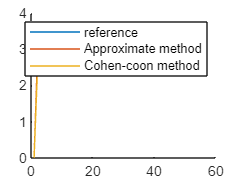



hold on
plot (Va(:))
plot(ans.Curve(:))
plot(ans.Curve1(:))

legend('reference', 'Approximate method', 'Cohen-coon method')

toc

Elapsed time is 18.115566 seconds.
